% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1' }      55          0.5        {'CMT'}
     {'d2' }      60          0.5        {'CMT'}
     {'d3' }      65          0.5        {'CMT'}
     {'d4' }      70          0.5        {'CMT'}
     {'d5' }      75          0.5        {'CMT'}
     {'d6' }      80          0.5        {'CMT'}
     {'d7' }      85          0.5        {'CMT'}
     {'d8' }      90          0.5        {'CMT'}
     {'d9' }      95          0.5        {'CMT'}
     {'d10'}      98          0.5        {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 1000×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1       {'d1'}     1576        50         {'C26'}
      2       {'d1'}     1555        50         {'C26'}
      3       {'d1'}     1557        50         {'C26'}
      4       {'d1'}     1578        50         {'C26'}
      5       {'d1'}     1560        50         {'C26'}
      6       {'d1'}     1553        50         {'C26'}
      7       {'d1'}     1579        50         {'C26'}
      8       {'d1'}     1563        50         {'C26'}
      9       {'d1'}     1555        50         {'C26'}
     10       {'d1'}     1576        50         {'C26'}
     11       {'d1'}     1558        50         {'C26'}
     12       {'d1'}     1554        50         {'C26'}
     13       {'d1'}     1

tools=readtable("..\data\tools.csv")

tools = 2×3 table
                tool                uncertainty      uom  
    ____________________________    ___________    _______

    {'proximity sensor tmd4906'}        0.05       {'SEC'}
    {'graduated rod'           }       0.005       {'MTR'}


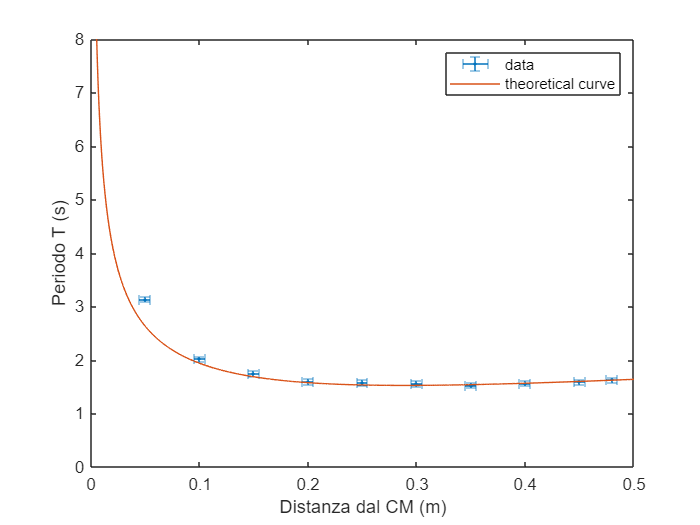


% unique distance
hd=unique(df2.distance);
ld=length(hd);

% defining variable
l0=1;                       % pendulum length
g=9.8;                      % gravitational acceleration
dg=0.1;                     % error gravitational acceleration
dt=tools.uncertainty(1);    % error t
dr=tools.uncertainty(2);    % errror distance

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % error t
d=zeros(ld,1);      % distance from CM
dd=zeros(ld,1);     % error distance
r=[0:0.0001:0.5];   % theoretical distance
gc=zeros(ld,1);     % gravitational acceleration calculated
dgc=zeros(ld,1);    % error gc
regc=zeros(ld,1);   % relative error gravitational acceleration
cfrg=zeros(ld,1);   % position first significant digit gravitational acceleration
uomd=string(zeros(ld,1));   % uom distance
uomg=string(zeros(ld,1));   % uom g
uomt=string(zeros(ld,1));   % uom t

% multiply *2, converting ms2s and rounding
df2.time=round(df2.time.*2./1000,2);
df2.uncertainty=df2.uncertainty/1000;

% core
for i=1:ld
    % calculating mean
    tm(i)=mean(table2array(df2(df2.distance==string(hd(i)),"time")));
    
    % error t
    dtm(i)=dt;

    % distance from CM
    d(i)=table2array(df1(df1.dimension==string(hd(i)),"value"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %convering cm2m
    
    % error distance from CM
    dd(i)=dr;

    % calculating gravitational acceleration
    gc(i)=(l0.^2.*pi.^2)./(3.*d(i).*tm(i).^2)+(4.*pi.^2.*d(i))./(tm(i).^2);
    dgc(i)=((pi.^2).*2.*l0.*dd(i))./(3.*d(i).*tm(i).^2)  +  (((((l0.^2).*pi.^2)/(3.*d(i).*tm(i).^4))+(4.*pi^2.*d(i)./tm(i).^4)).*8.*tm(i).*dtm(i))  +  abs(-((l0.^2.*pi.^2)./(3.*d(i).^2.*tm(i).^2)) + (4.*pi.^2)./(tm(i).^2)).*dd(i);
    
    % propagation of error g
    cfrg(i)=-floor(log10(dgc(i)));  % position first significant digit g
    dgc(i)=round(dgc(i),cfrg(i));   % round dgc
    gc(i)=round(gc(i),cfrg(i)+1);   % round g calculated

    % relative error g
    regc(i)=round(dgc(i)./gc(i)*100,2);
    
    % unit of measure
    uomd(i)="MTR";
    uomg(i)="MSK";
    uomt(i)="SEC";
end

% significant digits time
cfrt=-floor(log10(dt));         % position first significant digit time
tm=round(tm,cfrt);              % round 

% mean gravitational acceleration (output3)
gm=round(mean(gc(2:10)),1);
dgm=round(mean(dgc(2:10)),0);
regm=round((dgm/gm)*100,2);

% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l0.^2)./(12.*r))+r);

% plotting
plt=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,8])
legend('data','theoretical curve')

% converting array to string
d=string(d);
tm=string(tm);
gc=string(gc);
regc=string(regc);

for i=1:ld
    d(i)=sprintf('%.3f',d(i));
    tm(i)=sprintf('%.2f',tm(i));
    gc(i)=sprintf('%.1f',gc(i));
    regc(i)=sprintf('%.2f',regc(i));
end

% generating output 1
output1=array2table(cat(2,string(hd),d,gc,dgc,regc,uomg),"VariableNames",{'configuration','distance_CM','gravitational_acceleration','uncertainty','relative_error','uom'});
output1=sortrows(output1,"distance_CM");
output1=output1(:,{'configuration','gravitational_acceleration','uncertainty','relative_error','uom'}) %remove distance_CM

output1 = 10×5 table
    configuration    gravitational_acceleration    uncertainty    relative_error     uom 
    _____________    __________________________    ___________    ______________    _____

        "d1"                   "6.9"                   "2"           "28.99"        "MSK"
        "d2"                   "9.0"                   "2"           "22.22"        "MSK"
        "d3"                   "9.1"                   "2"           "21.98"        "MSK"
        "d4"                   "9.5"                   "3"           "31.58"        "MSK"
        "d5"                   "9.2"                   "2"           "21.74"        "MSK"
        "d6"                   "9.4"                   "2"           "21.28"        "MSK"
        "d7"                   "9.9"                   "3"           "30.30"        "MSK


% generating output2
output2=sortrows(array2table(cat(2,string(hd),d,dd,uomd,tm,dtm,uomt),"VariableNames",{'configuration','distance_CM','uncertainty_distance','uom_distance','time','uncertainty_time','uom_time'}),"distance_CM")

output2 = 10×7 table
    configuration    distance_CM    uncertainty_distance    uom_distance     time     uncertainty_time    uom_time
    _____________    ___________    ____________________    ____________    ______    ________________    ________

        "d1"           "0.050"            "0.005"              "MTR"        "3.14"         "0.05"          "SEC"  
        "d2"           "0.100"            "0.005"              "MTR"        "2.02"         "0.05"          "SEC"  
        "d3"           "0.150"            "0.005"              "MTR"        "1.75"         "0.05"          "SEC"  
        "d4"           "0.200"            "0.005"              "MTR"        "1.60"         "0.05"          "SEC"  
        "d5"           "0.250"            "0.005" 

% generating output3
output3=array2table(cat(2,gm,dgm,uomg(1),regm),"VariableNames",{'gravitational_acceleration','uncertainty','uom','relative_error'})

output3 = 1×4 table
    gravitational_acceleration    uncertainty     uom     relative_error
    __________________________    ___________    _____    ______________

              "9.5"                   "2"        "MSK"       "21.05"    


% exporting csv
writetable(output1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(output2,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')
writetable(output3,'..\data\output-data-3.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(plt,'..\img\plot.png');


% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);